n = 1;
L = 0;
%V = [2,8,50,200,800];
V_0m = [20];
%rhom = [0.2,0.3,0.5,0.7,0.9];
rhom = [0.5];
L=0;
Np = 100;
omega = linspace(0+10^(-5), 4, Np);

% Initialize the absalpha matrix
absalpha = zeros(length(V_0m), length(omega));


for l = 1:length(V_0m)
    rho = rhom(1);
    V_0 = V_0m(l);
    [k_Ln, q_Ln] = findkandq(L, V_0, rho);
    [N, B_0, C_0, D_0] = constantsunperturbed(L, k_Ln, q_Ln, rho); 
    for j = 1:length(omega)
        k_omega1 = sqrt(k_Ln^2 + 2 * (vpa(omega(j), 50) + 0.05 * 1i));
        s_omega1 = sqrt(2 * V_0 - k_omega1^2);
        k_omega2 = sqrt(k_Ln^2 + 2 * (-omega(j) - 0.05 * 1i));
        s_omega2 = sqrt(2 * V_0 - k_omega2^2); 
        [C_1p, C_21p, C_22p, C_3p] = constantsperturbed(N, B_0, C_0, D_0, k_Ln, k_omega1, q_Ln, s_omega1, rho);
        alphaplus = discpolarization(k_Ln, k_omega1, q_Ln, s_omega1, rho, N, B_0, C_0, D_0, C_1p, C_21p, C_22p, C_3p);
        [C_1n, C_21n, C_22n, C_3n] = constantsperturbed(N, B_0, C_0, D_0, k_Ln, k_omega2, q_Ln, s_omega2, rho);
        alphaminus = discpolarization(k_Ln, k_omega2, q_Ln, s_omega2, rho, N, B_0, C_0, D_0, C_1n, C_21n, C_22n, C_3n);
        absalpha(l, j) = 1/2 * abs(alphaplus + alphaminus);
    end
end

Exiting fzero: aborting search for an interval containing a sign change
    because complex function value encountered during search.
(Function value at -0.00028 is -0.1347-3.3035e-25i.)
Check function or try again with a different starting value.
Exiting fzero: aborting search for an interval containing a sign change
    because complex function value encountered during search.
(Function value at -0.00205237 is -0.1347-3.835e-17i.)
Check function or try again with a different starting value.
Exiting fzero: aborting search for an interval containing a sign change
    because complex function value encountered during search.
(Function value at -0.00382474 is -0.1347-3.835e-17i.)
Check function or try again with a different starting value.
Exiting fzero: aborting search for an interval containing a sign change
    because complex function value encountered during search.
(Function value at -0.0055971 is -0.1347+1.0566e-22i.)
Check function or try again with a different starting value.
Ex



hold on
for l=1:length(V_0m)
plot(omega, absalpha(l,:)); 
end
xlabel('$\mathrm{Frequency} \ \omega R^2$', 'Interpreter', 'latex', 'FontSize', 18);
ylabel('$\mathrm{Polarizability} \ |\alpha(\omega)|/R^4$', 'Interpreter', 'latex', 'FontSize', 18);

hold off
file_path = '~/Documents/AAU/8.semester/P8/Results/resultsABringfinitepotentialanalytical/Data/absalpharho0.9V_02481020N500.csv';
writematrix(absalpha, file_path);
legend('$V_0 =4$','$V_0 = 8$','$V_0 = 10$','$V_0 =20$', 'Interpreter', 'latex', 'FontSize', 10,'Location', 'northeast')

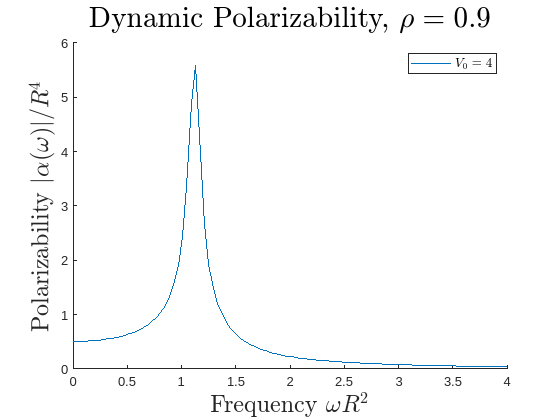

title('Dynamic Polarizability, $\rho = 0.9$', 'Interpreter', 'latex','FontSize',22);
outputDir = '~/Documents/AAU/8.semester/P8/Results/ResultsABringfinitepotentialnumericalanalytical/Figures';
filename = fullfile(outputDir, 'rho0.9V_0481020.svg');
print(filename, '-dsvg');